# Bespoke Noise Generator

This script applies a scaled noise correction to meet a user defined SNR. It:

- calculates the signal power for each element of the baseline data (complex array input).

- determines the required noise power to achieve the desired SNR.

- generates the complex noise matrix for each element.

- adds the noise matrix to the original matrix to create the noisy matrix.

- the noisy matrix is then processed by the slice_SNR function.

- the baseline SNR vs noisy matrix SNR is visualised; as well as the SNR, Signal and Noise for each the Baseline and the Noisy data across subplots.

passive_required_SNR_dB = 15; % Desired SNR in dB [dB].
passive_required_SNR_linear = 10^(passive_required_SNR_dB / 10); % [linear]

passive_baseline_matrix_complex = passive_inputdata; % [complex]
passive_baseline_matrix_linear = passive_slices_range_doppler_abs; % [linear]

% Calculate signal power for each element
passive_signalPower_linear = zeros(1, length(passive_baseline_matrix_linear)); % [linear]
for i = 1:length(passive_baseline_matrix_linear)
    passive_signalPower_linear(i) = (max(passive_baseline_matrix_linear{i}(:))).^2; % [linear]
end

% Calculate noise power for each element
passive_noisePower_linear = passive_signalPower_linear / passive_required_SNR_linear; % [linear]

% Generate a noise matrix for each element
passive_noise_complex = cell(1, length(passive_baseline_matrix_complex));
for i = 1:length(passive_baseline_matrix_complex)
    % Use sqrt(noisePower_linear(i)/2) for complex noise
    passive_noise_complex{i} = sqrt(passive_noisePower_linear(i)/2) * ...
        (randn(size(passive_baseline_matrix_complex{i})) + 1i .* randn(size(passive_baseline_matrix_complex{i}))); % [complex]
end

% Add the original matrix to the new noise matrix
passive_noisyMatrix_complex = cell(1, length(passive_baseline_matrix_complex));
for i = 1:length(passive_baseline_matrix_complex)
    passive_noisyMatrix_complex{i} = passive_baseline_matrix_complex{i} + passive_noise_complex{i};
end

% Calculate linear and dB values for each element in noise_complex
passive_noise_linear = cell(1, length(passive_noise_complex));
passive_noise_dB = cell(1, length(passive_noise_complex));
for i = 1:length(passive_noise_complex)
    passive_noise_linear{i} = abs(passive_noise_complex{i});  % Linear values
    passive_noise_dB{i} = 20*log10(abs(passive_noise_complex{i}));  % dB values
end

% Add the original matrix to the new noise matrix to generate the noisy matrix
passive_noisyMatrix_complex = cell(1, length(passive_baseline_matrix_complex));
for i = 1:length(passive_baseline_matrix_complex)
    passive_noisyMatrix_complex{i} = passive_baseline_matrix_complex{i} + passive_noise_complex{i}; % [complex]
end  

### Use slice_SNR to process the noisyMatrix

% User defined ROI indices
passive_roi_indices_rows = 320:420; % input to slice_SNR func to calculate noise of roi
passive_roi_indices_cols = 35:45;   % input to slice_SNR func to calculate noise of roi
noisy_passive_signal=zeros(1,length(passive_noisyMatrix_complex)); % [dB] once func populates
noisy_passive_noise=zeros(1,length(passive_noisyMatrix_complex)); % [dB] once func populates
noisy_passive_noise_abs=zeros(1,length(passive_noisyMatrix_complex)); % absolute mean noise (not dB) once func populates
noisy_passive_SNR=zeros(1,length(passive_noisyMatrix_complex)); % [dB] once func populates
noisy_passive_slices_range_doppler = createArrays(length(passive_noisyMatrix_complex), size(passive_noisyMatrix_complex{1,1})); % [dB] once func populates
noisy_passive_slices_range_doppler_abs = createArrays(length(passive_noisyMatrix_complex), size(passive_noisyMatrix_complex{1,1})); % absolute not dB, once func populates
noisy_passive_signal_idx = zeros(1,length(passive_noisyMatrix_complex));

for i=1:length(passive_noisyMatrix_complex)
    [noisy_passive_signal(i),...
        noisy_passive_noise(i),...
        noisy_passive_SNR(i),...
        noisy_passive_slices_range_doppler{i},...
        noisy_passive_signal_idx(i),...
        noisy_passive_noise_abs(i),...
        noisy_passive_slices_range_doppler_abs{i}]=slice_SNR(passive_noisyMatrix_complex{1,i}, passive_roi_indices_rows, passive_roi_indices_cols);
end   

Calculating Mean Values for Plot

passive_mean_passive_SNR_dB = mean(passive_SNR) % mean mean of the baseline SNR [db]

passive_mean_passive_SNR_dB = 40.2718

passive_mean_noisy_passive_SNR_dB = mean(noisy_passive_SNR) % mean of the noise SNR [dB]

passive_mean_noisy_passive_SNR_dB = 16.2327

passive_mean_delta = -(passive_mean_passive_SNR_dB - passive_mean_noisy_passive_SNR_dB) % - to show reduction [dB]

passive_mean_delta = -24.0391

### Visualising the Baseline Matrix & the Noisy Matrix

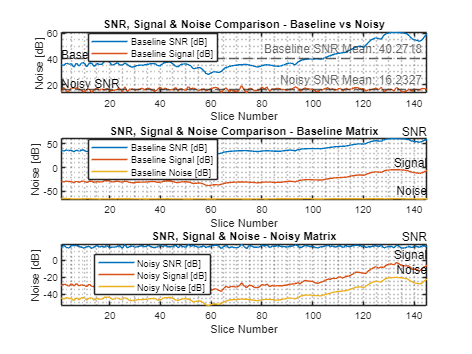

figure;
fig = figure;
subplot(3,1,1)
plot(1:length(passive_SNR), passive_SNR, ...
    1:length(noisy_passive_SNR), noisy_passive_SNR)

grid minor
title('SNR, Signal & Noise Comparison - Baseline vs Noisy');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(passive_SNR)])
% Add text annotations
text(1, (passive_SNR(1:1))*1.05, 'Baseline SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left');
text(1, (noisy_passive_SNR(1:1))*1.05, 'Noisy SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left');
yline(passive_mean_passive_SNR_dB, '--', ...
    ['Baseline SNR Mean: ' num2str(passive_mean_passive_SNR_dB)], ...
    'LineWidth', 0.25);
%    'FontSize', 6);
yline(passive_mean_noisy_passive_SNR_dB, '--', ...
    ['Noisy SNR Mean: ' num2str(passive_mean_noisy_passive_SNR_dB)], ...
    'LineWidth', 0.25);
%    'FontSize', 6);
legend( 'Baseline SNR [dB]', ...
    'Baseline Signal [dB]',  ...
    'location', 'best')

subplot(3,1,2)
plot(1:length(passive_SNR), passive_SNR, ...
    1:length(passive_signal), passive_signal, ...
    1:length(passive_noise), passive_noise)
legend( 'Baseline SNR [dB]', ...
    'Baseline Signal [dB]', ...
    'Baseline Noise [dB]',...
    'location', 'best')
grid minor
title('SNR, Signal & Noise Comparison - Baseline Matrix');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(passive_SNR)])
% Add text annotations
text(length(passive_SNR), max(passive_SNR), 'SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(length(passive_signal), max(passive_signal), 'Signal', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(length(passive_noise), max(passive_noise), 'Noise', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');

subplot(3,1,3)
plot(1:length(noisy_passive_SNR), noisy_passive_SNR, ...
    1:length(noisy_passive_signal), noisy_passive_signal, ...
    1:length(noisy_passive_noise), noisy_passive_noise)
legend( 'Noisy SNR [dB]', ...
    'Noisy Signal [dB]', ...
    'Noisy Noise [dB]',...
    'location', 'best')
grid minor
title('SNR, Signal & Noise - Noisy Matrix');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(passive_SNR)])
% Add text annotations
text(145, max(noisy_passive_SNR), 'SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(145, max(noisy_passive_signal), 'Signal', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(145, max(noisy_passive_noise), 'Noise', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');

Save figure to repo

% fig_name = figure_directory + bracket + inputstructure.name + ' Signal Peak subplots - Range Vs Slice and Doppler Vs Slice';
% savefig(figure_title)
% saveas(fig, fig_name + '.png')

#### Observation:

The differences in the profiles of 'passive_SNR' and the 'noisy_passive_SNR' can be attributed to the nature of the signal and noise addition.

Baseline SNR ('passive_SNR'):  this represents the Signal-to-Noise Ratio (SNR) of the original data. The profile shows the quality of the signal across different slices.

Noisy Signal SNR ('noisy_passive_SNR'):  this represents the SNR after adding artificial noise to the original data. The artificial noise affects the SNR, and you are seeing a different profile due to the added noise. The flatter profile may indicate that the added noise is affecting different slices uniformly.

#### Plot Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean

Moving the Noisy SNR signal to have a mean = 0dB

noisy_passive_SNR_dB_zeroed = noisy_passive_SNR - passive_mean_noisy_passive_SNR_dB; % [dB]

Plot the Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean

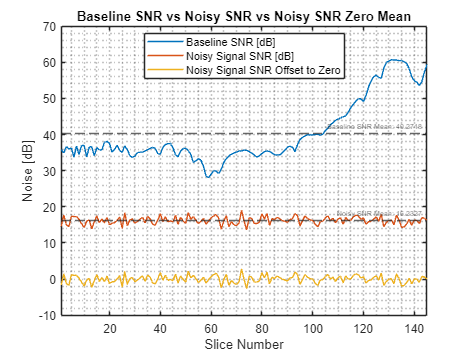

figure;
fig = figure;
plot(1:length(passive_SNR), passive_SNR, ...
    1:length(noisy_passive_SNR), noisy_passive_SNR, ...
    1:length(noisy_passive_SNR_dB_zeroed), noisy_passive_SNR_dB_zeroed)
yline(passive_mean_passive_SNR_dB, '--', ...
    ['Baseline SNR Mean: ' num2str(passive_mean_passive_SNR_dB)], ...
    'LineWidth', 0.25, ...
    'FontSize', 6);
yline(passive_mean_noisy_passive_SNR_dB, '--', ...
    ['Noisy SNR Mean: ' num2str(passive_mean_noisy_passive_SNR_dB)], ...
    'LineWidth', 0.25, ...
    'FontSize', 6);
legend( 'Baseline SNR [dB]', ...
    'Noisy Signal SNR [dB]', ...
    'Noisy Signal SNR Offset to Zero', '', '', ...
    'location', 'best')
grid minor
title('Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(noisy_passive_SNR)])

Save figure to repo

% fig_name = figure_directory + bracket + inputstructure.name + ' Signal Peak subplots - Range Vs Slice and Doppler Vs Slice';
% savefig(figure_title)
% saveas(fig, fig_name + '.png')